Due sinusoidi immerse in rumore gaussiano

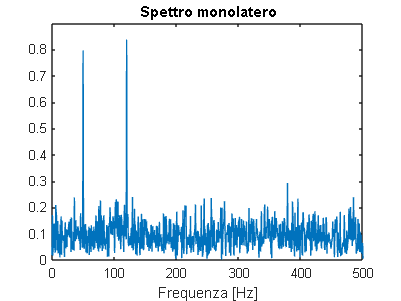

Fs = 1000;
L = 1500;
t = (0:L-1)/Fs;
s = 0.7*sin(2*pi*50*t) + sin(2*pi*120*t);
x = s + 2*randn(size(t));
X = fft(x)/L;
X(L/2+2:end) = [];
X(2:end-1) = 2*X(2:end-1);
f = (0:L/2)*Fs/L;
plot(f,abs(X))
title("Spettro monolatero")
xlabel("Frequenza [Hz]")